clc; clear all; close all;

%% Uploading Data Sets (expects columns: x, y, z, p)
Data   = xlsread('new_data_cluster_1.csv');   % <— your file name here

Choice = 0.70;                   % Train/Test split fraction
Np     = 11;                      % Number of input columns

%% Data Randomization (aligned with your template)
rand('seed',3100);
Length_Data  = length(Data);
Random_Nums  = randperm(Length_Data,Length_Data)';
Data_random  = Data(Random_Nums, :);

Data_Tr      = Data_random(1 : ceil(Length_Data * Choice), :);
Data_Tst     = Data_random(length(Data_Tr)+1 : end, :);

Data_Tr      = sortrows(Data_Tr,1);
Data_Tst     = sortrows(Data_Tst,1);

% Training_Depth  = Data_Tr(:,1);  % keep commented if depth plotting is needed later
% Testing_Depth   = Data_Tst(:,1);

Input_Training   = Data_Tr(:, 1 : Np);
Output_Training  = Data_Tr(:, Np + 1);

Input_Testing    = Data_Tst(:, 1 : Np);
Output_Testing   = Data_Tst(:, Np + 1);

mD = Data(:, Np);              % measured (real) values (whole dataset)

%% Sweep settings
neuron_range = 30:40;                     % hidden layer sizes
transfer_list = {'purelin','tansig'};    % hidden TFs to try

% Store results for ALL cases
Results = {};  % {'transfer_fn', neurons, 'AAPE_train','MSE_train','R2_train','AAPE_test','MSE_test','R2_test'}

%% Loop over transfer functions and neuron counts (keeps your training params)
for t = 1:numel(transfer_list)
    tf_name = transfer_list{t};
    for L1_Neurons = neuron_range

        % --- Create a Neural Network (single hidden layer) ---
        net  = fitnet(L1_Neurons);     % single hidden layer

        % Keep your training configuration
        net.trainFcn                = 'trainbfg';    % Levenberg-Marquardt
        net.trainParam.showWindow   = 1;            % show training GUI
        net.layers{1}.transferFcn   = tf_name;      % 'purelin' OR 'tansig'
        net.trainParam.epochs       = 1000;         % max epochs
        net.trainParam.lr           = 0.12;         % learning rate
        net.trainParam.mc           = 0.6;          % momentum
        net.trainParam.min_grad     = 0;
        net.trainParam.mu_max       = 1E100;

        % Internal divider for Train/Validation only (we already have external Test)
        net.divideParam.trainRatio  = 0.75;
        net.divideParam.valRatio    = 0.25;
        net.divideParam.testRatio   = 0.00;

        % --- Train on TRAINING set ---
        [net, tr]           = train(net, Input_Training', Output_Training');
        Results_Training    = net(Input_Training')';  % predictions (train)
        Results_Testing     = net(Input_Testing')';   % predictions (test)

        % --- Metrics (aligned with your post-processing) ---
        AAPE_Train = mean(abs((Output_Training - Results_Training)./Output_Training));
        AAPE_Test  = mean(abs((Output_Testing - Results_Testing)./Output_Testing));

        MSE_Train  = mean((Output_Training - Results_Training).^2);
        MSE_Test   = mean((Output_Testing - Results_Testing).^2);

        % R^2 like your code (uses variance of predictions)
        R_squared_training = 1 - sum((Results_Training - Output_Training).^2) ...
                                / sum((Results_Training - mean(Results_Training)).^2);
        R_squared_testing  = 1 - sum((Results_Testing  - Output_Testing ).^2) ...
                                / sum((Results_Testing  - mean(Results_Testing )).^2);

        % --- Outliers relative to global measured range (same logic as your code) ---
        max_mD = max(mD);
        min_mD = min(mD);

        count_higher_values_tr = sum(Results_Training > max_mD);
        count_lower_values_tr  = sum(Results_Training < min_mD);

        count_higher_values_ts = sum(Results_Testing > max_mD);
        count_lower_values_ts  = sum(Results_Testing < min_mD);

        % --- Log to Command Window (optional) ---
        fprintf('\n[%s] Neurons=%d\n', tf_name, L1_Neurons);
        fprintf('Train: AAPE=%.6f, MSE=%.6f, R2=%.6f | +ve=%d, -ve=%d\n', ...
            AAPE_Train, MSE_Train, R_squared_training, count_higher_values_tr, count_lower_values_tr);
        fprintf('Test : AAPE=%.6f, MSE=%.6f, R2=%.6f | +ve=%d, -ve=%d\n', ...
            AAPE_Test,  MSE_Test,  R_squared_testing,  count_higher_values_ts, count_lower_values_ts);

        % --- Collect into results table ---
        Results(end+1,:) = { ...
            tf_name, L1_Neurons, ...
            AAPE_Train, MSE_Train, R_squared_training, ...
            AAPE_Test,  MSE_Test,  R_squared_testing, ...
            count_higher_values_tr, count_lower_values_tr, ...
            count_higher_values_ts, count_lower_values_ts};
    end
end


[purelin] Neurons=30


Train: AAPE=0.249197, MSE=3.095963, R2=0.497509 | +ve=36, -ve=0


Test : AAPE=0.404382, MSE=6.681690, R2=0.122702 | +ve=15, -ve=0



[purelin] Neurons=31


Train: AAPE=0.236204, MSE=3.537089, R2=0.439455 | +ve=33, -ve=0


Test : AAPE=0.323992, MSE=7.507129, R2=-0.076904 | +ve=17, -ve=0



[purelin] Neurons=32


Train: AAPE=0.247742, MSE=3.469258, R2=0.543880 | +ve=34, -ve=0


Test : AAPE=0.327589, MSE=6.042624, R2=0.273622 | +ve=19, -ve=0



[purelin] Neurons=33


Train: AAPE=0.283439, MSE=3.270866, R2=0.594969 | +ve=35, -ve=0


Test : AAPE=0.451922, MSE=7.954882, R2=0.230306 | +ve=16, -ve=0



[purelin] Neurons=34


Train: AAPE=0.265202, MSE=3.121416, R2=0.616476 | +ve=33, -ve=0


Test : AAPE=0.416307, MSE=8.203825, R2=0.170769 | +ve=14, -ve=0



[purelin] Neurons=35


Train: AAPE=0.320409, MSE=3.957383, R2=0.646536 | +ve=33, -ve=0


Test : AAPE=0.434287, MSE=8.229463, R2=0.386789 | +ve=14, -ve=0



[purelin] Neurons=36


Train: AAPE=0.316368, MSE=3.299804, R2=0.616069 | +ve=36, -ve=0


Test : AAPE=0.443597, MSE=7.879532, R2=0.282408 | +ve=14, -ve=0



[purelin] Neurons=37


Train: AAPE=0.408733, MSE=4.609822, R2=0.480432 | +ve=35, -ve=1


Test : AAPE=0.628373, MSE=9.787049, R2=0.410137 | +ve=14, -ve=3



[purelin] Neurons=38


Train: AAPE=0.253448, MSE=3.168312, R2=0.560004 | +ve=34, -ve=0


Test : AAPE=0.383187, MSE=7.248904, R2=0.122736 | +ve=16, -ve=0



[purelin] Neurons=39


Train: AAPE=1.157770, MSE=42.572404, R2=0.159683 | +ve=31, -ve=11


Test : AAPE=1.675832, MSE=54.334913, R2=0.072965 | +ve=13, -ve=5



[purelin] Neurons=40


Train: AAPE=0.321703, MSE=3.543165, R2=0.487731 | +ve=36, -ve=0


Test : AAPE=0.531992, MSE=9.213447, R2=-0.039091 | +ve=16, -ve=0



[tansig] Neurons=30


Train: AAPE=0.310146, MSE=2.790467, R2=0.671458 | +ve=36, -ve=0


Test : AAPE=0.674170, MSE=21.368178, R2=-0.432429 | +ve=14, -ve=2



[tansig] Neurons=31


Train: AAPE=0.546025, MSE=8.000147, R2=0.182504 | +ve=38, -ve=1


Test : AAPE=0.793827, MSE=14.265531, R2=0.357458 | +ve=15, -ve=1



[tansig] Neurons=32


Train: AAPE=0.304670, MSE=6.827223, R2=0.547532 | +ve=33, -ve=0


Test : AAPE=0.776859, MSE=25.309666, R2=-0.283531 | +ve=16, -ve=1



[tansig] Neurons=33


Train: AAPE=0.286381, MSE=2.484499, R2=0.696519 | +ve=36, -ve=0


Test : AAPE=0.423336, MSE=10.119038, R2=0.163285 | +ve=14, -ve=0



[tansig] Neurons=34


Train: AAPE=0.308326, MSE=4.652253, R2=0.531325 | +ve=32, -ve=0


Test : AAPE=0.482412, MSE=7.629789, R2=0.474250 | +ve=13, -ve=1



[tansig] Neurons=35


Train: AAPE=0.339004, MSE=3.050632, R2=0.553557 | +ve=41, -ve=0


Test : AAPE=0.417075, MSE=7.799499, R2=0.173051 | +ve=17, -ve=0



[tansig] Neurons=36


Train: AAPE=0.333032, MSE=4.721523, R2=0.250778 | +ve=36, -ve=0


Test : AAPE=0.371518, MSE=5.672686, R2=0.047832 | +ve=14, -ve=1



[tansig] Neurons=37


Train: AAPE=0.173020, MSE=1.304453, R2=0.876130 | +ve=36, -ve=0


Test : AAPE=0.582887, MSE=14.683713, R2=-0.071354 | +ve=15, -ve=0



[tansig] Neurons=38


Train: AAPE=0.306539, MSE=3.886517, R2=0.500862 | +ve=35, -ve=0


Test : AAPE=0.386261, MSE=5.762239, R2=0.381816 | +ve=15, -ve=1



[tansig] Neurons=39


Train: AAPE=0.322057, MSE=4.670954, R2=0.448637 | +ve=37, -ve=0


Test : AAPE=0.635341, MSE=15.835898, R2=0.158635 | +ve=16, -ve=1



[tansig] Neurons=40


Train: AAPE=0.849254, MSE=14.255833, R2=-0.149010 | +ve=41, -ve=0


Test : AAPE=0.702690, MSE=13.569100, R2=-0.246914 | +ve=16, -ve=0



%% Build results table and display ALL cases
T = cell2table(Results, 'VariableNames', { ...
    'transfer_fn','neurons', ...
    'AAPE_train','MSE_train','R2_train', ...
    'AAPE_test','MSE_test','R2_test', ...
    'OutliersTrain_Pos','OutliersTrain_Neg', ...
    'OutliersTest_Pos','OutliersTest_Neg'});

% Sort for readability: by transfer_fn then neurons
T = sortrows(T, {'transfer_fn','neurons'});
disp('--- ALL RESULTS ---');

--- ALL RESULTS ---


disp(T);

    transfer_fn    neurons    AAPE_train    MSE_train    R2_train    AAPE_test    MSE_test     R2_test     OutliersTrain_Pos    OutliersTrain_Neg    OutliersTest_Pos    OutliersTest_Neg
    ___________    _______    __________    _________    ________    _________    ________    _________    _________________    _________________    ________________    ________________

    {'purelin'}      30         0.2492        3.096       0.49751     0.40438      6.6817        0.1227           36                    0                   15                  0        
    {'purelin'}      31         0

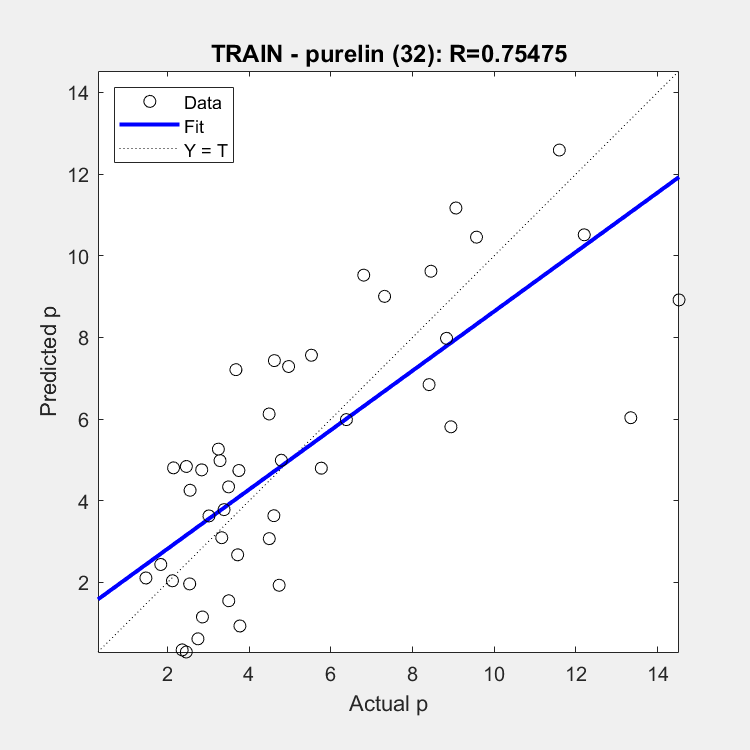

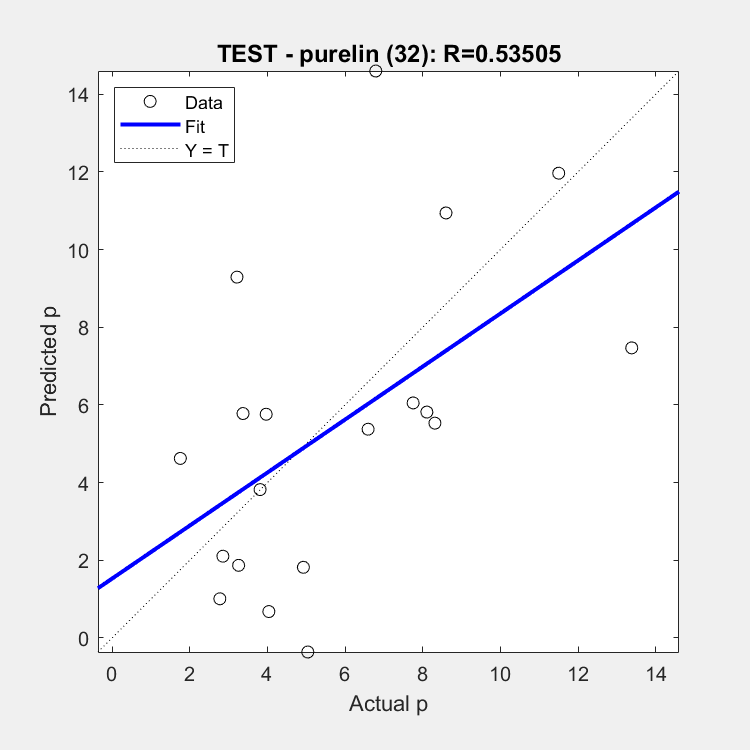

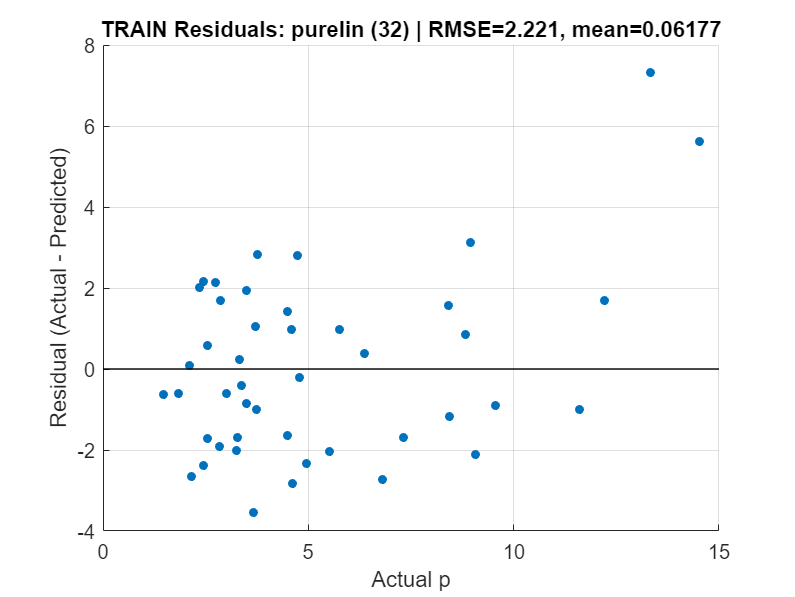

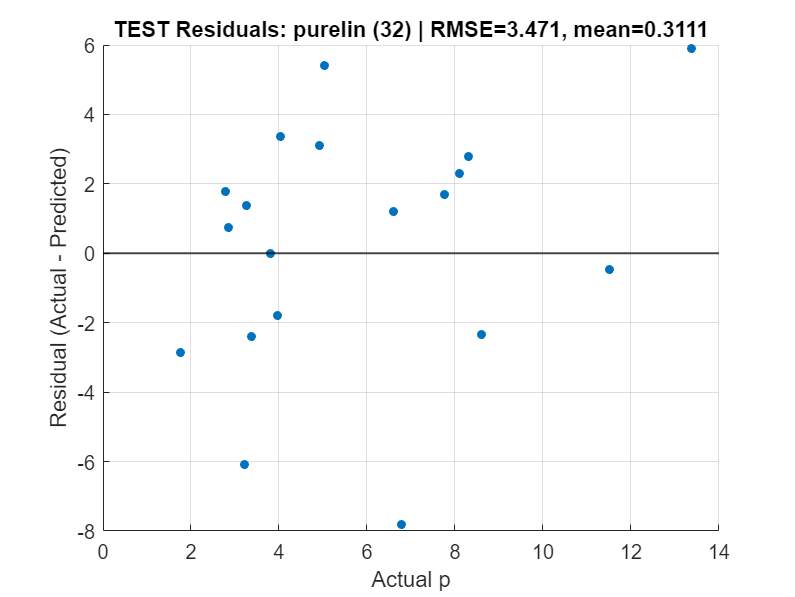

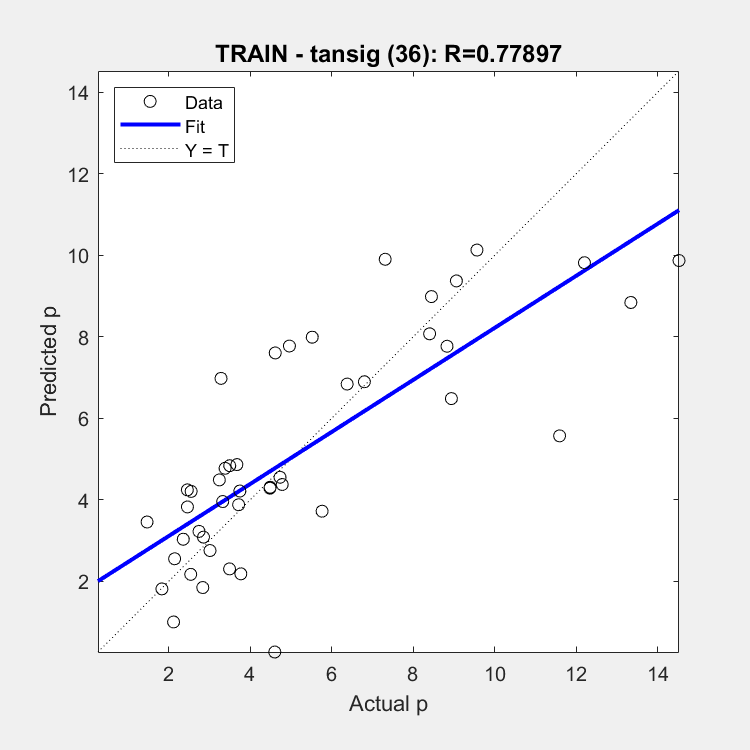

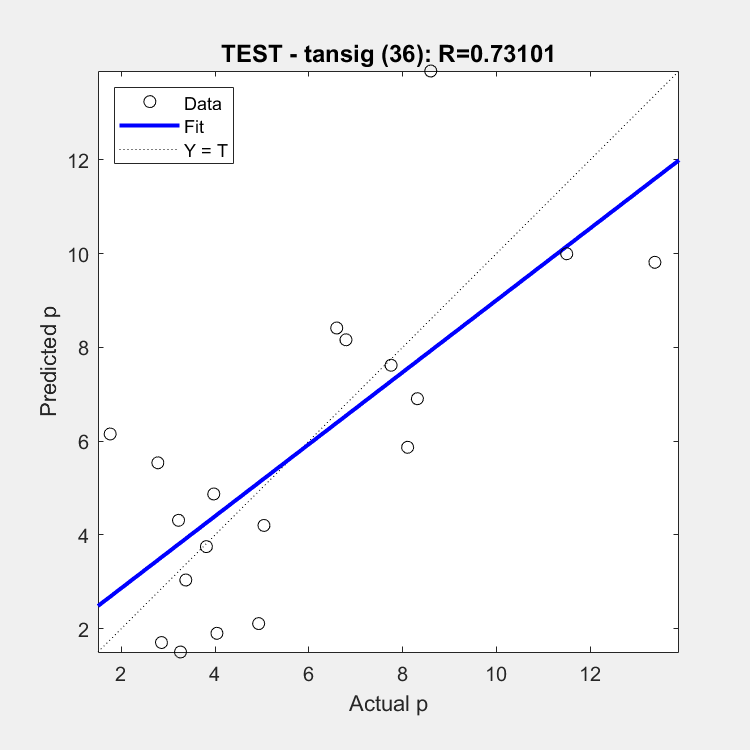

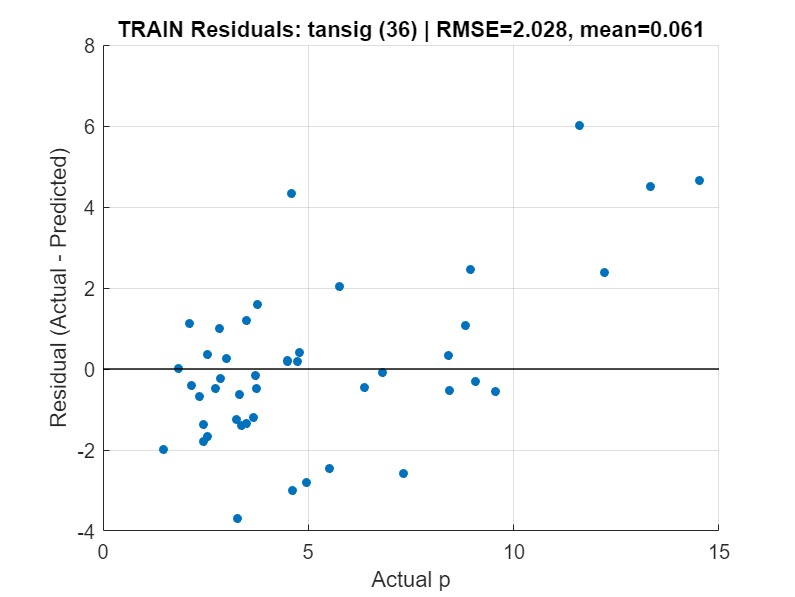

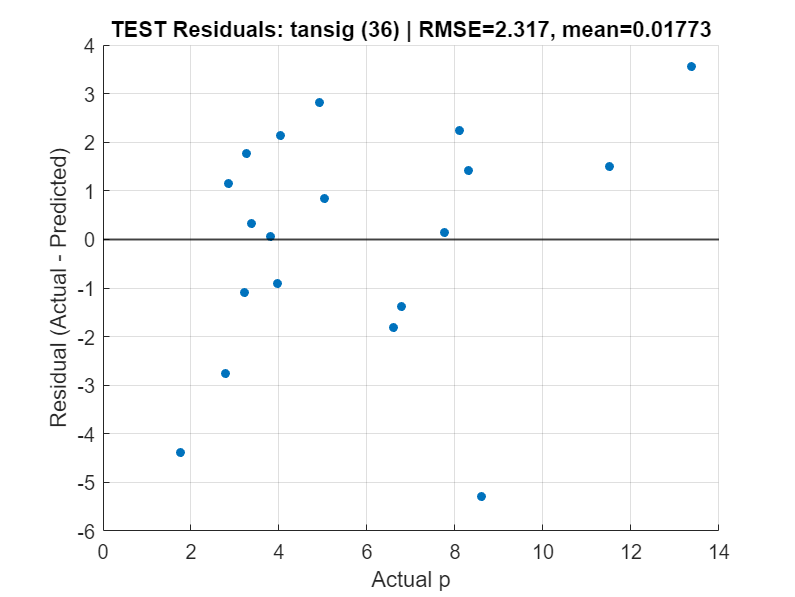


% Save to Excel
writetable(T, 'ann_results_all_0.xlsx', 'Sheet', 'results');

%% Optional: Regression plots for the best case per transfer function
% Pick best by lowest MSE_test within each transfer_fn
Tf = unique(T.transfer_fn);
for k = 1:numel(Tf)
    mask = strcmp(T.transfer_fn, Tf{k});
    Tk = T(mask, :);
    [~, idxBest] = min(Tk.MSE_test);
    bestNeurons = Tk.neurons(idxBest);

    % Re-train that best model to get the final plots
    net = fitnet(bestNeurons);
    net.trainFcn                = 'trainbfg';
    net.trainParam.showWindow   = 1;
    net.layers{1}.transferFcn   = Tf{k};
    net.trainParam.epochs       = 1000;
    net.trainParam.lr           = 0.12;
    net.trainParam.mc           = 0.6;
    net.trainParam.min_grad     = 0;
    net.trainParam.mu_max       = 1E100;
    net.divideParam.trainRatio  = 0.75;
    net.divideParam.valRatio    = 0.25;
    net.divideParam.testRatio   = 0.00;

    [net,~]          = train(net, Input_Training', Output_Training');
    ytr_pred         = net(Input_Training')';
    yte_pred         = net(Input_Testing')';

    figure('Name', sprintf('Regression - %s (%d neurons) - TRAIN', Tf{k}, bestNeurons));
    plotregression(Output_Training, ytr_pred, sprintf('TRAIN - %s (%d)', Tf{k}, bestNeurons));
    xlabel('Actual p'); ylabel('Predicted p');

    figure('Name', sprintf('Regression - %s (%d neurons) - TEST', Tf{k}, bestNeurons));
    plotregression(Output_Testing, yte_pred, sprintf('TEST - %s (%d)', Tf{k}, bestNeurons));
    xlabel('Actual p'); ylabel('Predicted p');

    % Residuals
    res_tr = Output_Training - ytr_pred;
    res_te = Output_Testing  - yte_pred;

    % Quick stats (optional)
    rmse_tr = sqrt(mean(res_tr.^2));
    rmse_te = sqrt(mean(res_te.^2));
    mu_tr   = mean(res_tr);
    mu_te   = mean(res_te);

    % --- TRAIN residuals ---
    figure('Name', sprintf('Residuals vs Actual - TRAIN - %s (%d)', Tf{k}, bestNeurons));
    scatter(Output_Training, res_tr, 20, 'filled'); grid on;
    hold on; yline(0,'k-','LineWidth',1); hold off;
    xlabel('Actual p');
    ylabel('Residual (Actual - Predicted)');
    title(sprintf('TRAIN Residuals: %s (%d) | RMSE=%.4g, mean=%.4g', Tf{k}, bestNeurons, rmse_tr, mu_tr));

    % --- TEST residuals ---
    figure('Name', sprintf('Residuals vs Actual - TEST - %s (%d)', Tf{k}, bestNeurons));
    scatter(Output_Testing, res_te, 20, 'filled'); grid on;
    hold on; yline(0,'k-','LineWidth',1); hold off;
    xlabel('Actual p');
    ylabel('Residual (Actual - Predicted)');
    title(sprintf('TEST Residuals: %s (%d) | RMSE=%.4g, mean=%.4g', Tf{k}, bestNeurons, rmse_te, mu_te));
    tag = sprintf('%s_%d', Tf{k}, bestNeurons);

% Regression data tables
TrainReg = table(Output_Training, ytr_pred, ...
    'VariableNames', {'Actual_p','Predicted_p'});

TestReg  = table(Output_Testing,  yte_pred, ...
    'VariableNames', {'Actual_p','Predicted_p'});

% Residual data tables
TrainRes = table(Output_Training, res_tr, ...
    'VariableNames', {'Actual_p','Residual_ActualMinusPred'});

TestRes  = table(Output_Testing,  res_te, ...
    'VariableNames', {'Actual_p','Residual_ActualMinusPred'});

% Optional: compute best-fit line (Pred = a*Actual + b) for Excel
p_tr = polyfit(Output_Training, ytr_pred, 1);
p_te = polyfit(Output_Testing,  yte_pred, 1);

FitLines = table( ...
    p_tr(1), p_tr(2), p_te(1), p_te(2), ...
    'VariableNames', {'Train_slope','Train_intercept','Test_slope','Test_intercept'});

% Optional: 1:1 line endpoints (Excel can plot as a line)
mn = min([Output_Training; Output_Testing; ytr_pred; yte_pred]);
mx = max([Output_Training; Output_Testing; ytr_pred; yte_pred]);
OneToOne = table([mn; mx],[mn; mx], 'VariableNames', {'x','y'});

% Write to one Excel file, multiple sheets
outXlsx = 'plot_data_for_excel.xlsx';
writetable(TrainReg, outXlsx, 'Sheet', ['TrainReg_' tag]);
writetable(TestReg,  outXlsx, 'Sheet', ['TestReg_'  tag]);
writetable(TrainRes, outXlsx, 'Sheet', ['TrainRes_' tag]);
writetable(TestRes,  outXlsx, 'Sheet', ['TestRes_'  tag]);
writetable(FitLines, outXlsx, 'Sheet', ['Fit_'      tag]);
writetable(OneToOne, outXlsx, 'Sheet', ['OneToOne_' tag]);

% Also save CSVs if you prefer
writetable(TrainReg, ['TrainReg_' tag '.csv']);
writetable(TestReg,  ['TestReg_'  tag '.csv']);
writetable(TrainRes, ['TrainRes_' tag '.csv']);
writetable(TestRes,  ['TestRes_'  tag '.csv']);
end